# 2LAB 6: DESIGN OF SPEED ESTIMATOR for DC MOTOR

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Hongtao Xu';
Students.ID = '260773785';
%---------------------------------------

## **0. Objectives**

In this lab, we will use the angular velocity measurements from the DC Motor to estimate the full state of the DC Motor, i.e. angular velocity and the current. We will use `MATLAB` to place the poles of the Luenberger observer and run a state estimator both in continuous and discrete time.

To initiate a connection with the virtual motor, run the following:

Motor = VirtualMotor();

## **1. A State-Space Representation of DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

<<fig_dcmotorshematic.png>>

We can model the DC motor using the armature current $i$ and the angular speed $\omega$. The dynamics of the DC motor are given by the following two coupled differential equations:


$$ J \displaystyle \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \displaystyle \frac{d i}{dt} + R i = v - K_e \omega $$


where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-05; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor model by the following state-space representation


$$ \displaystyle \frac{d}{dt}x(t) = \pmatrix{ -\displaystyle \frac{b}{J}
& \displaystyle \frac{K_t}{J} \cr -\displaystyle \frac{K_e}{L} &
-\displaystyle \frac{R}{L} } x(t) + \pmatrix{ 0 \cr \displaystyle
\frac{1}{L} } v(t) $$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \pmatrix{ \omega(t) \cr i(t) } $$


Note that if we think of the angular velocity $\omega(t)$ as the output of this system, then $C = \pmatrix{1 & 0}$ and


$$ \omega(t) = C x(t) $$


In this case, the transfer function from the voltage $v(t)$ to the angular velocity $\omega(t)$ is given by


$$ G_o(s) = C (s I - A)^{-1} B $$


The state-space representation of the DC Motor can be written as

A = [ ...
    -Param.b / Param.J, Param.Kt / Param.J; ...
    -Param.Ke / Param.L, -Param.R / Param.L];
B = [ ...
    0; ...
    1 / Param.L];
C = [1, 0];
D = 0;
Go = ss(A, B, C, D);
tf(Go)


ans =
 
        9.444e04
  --------------------
  s^2 + 467.2 s + 3444
 
Continuous-time transfer function.



## *Question 1 (1 mark)*

Using `MATLAB`, compute the eigenvalues of the observability matrix of the system? Based on the eigenvalues, is the system observable?

CA = C*A;
Ofuc = [C;CA];
eigen = eig(Ofuc)

eigen =         1700
           1



IsObservable = det(Ofuc)

IsObservable = 1700

## **2. State Estimator Design**

Knowing the system state is necessary to solve many control problems; for example, stabilizing a system using state feedback. In most practical cases, the physical state of the system cannot be determined by direct observation. Instead, indirect effects of the internal state are observed by way of the system outputs. A simple example is that of vehicles in a tunnel: the rates and velocities at which vehicles enter and leave the tunnel can be observed directly, but the exact state inside the tunnel can only be estimated. If a system is observable, it is possible to fully reconstruct the system state from its output measurements using the state observer.

In this lab, we assume that the full state feedback is not available and only the angular speed ($\omega(t)$) is available. The angular velocity measured directly from the DC Motor is affected by an unwanted noise. The sensor noise can vary greatly as it is produced by several different effects, however, it is usually approximated to an additive white Gaussian noise. In this case, the intensity of the noise can be measured by its variance.

The objective of this state estimator will be to:

- Estimate the current $i(t)$.

- Reduce the variance of the sensor noise in both the angular velocity and the current estimates.

In `MATLAB`, the function `place` is designed for choosing the controller gain $K$. Yet by using the duality between choosing controller gain $K$ and choosing estimator gain $L$ we can use `place` to identify the gain $L$.

## *Question 2 (1 mark)*

Using the `place` command design a state estimator gain $L$ for the system ($A, \, C$) such that the eigenvalues of the estimation error are $P_{1,2} = -50 \pm 50 j$.

p1 = 50 * (-1 + 1j);
p2 = 50 * (-1 - 1j);

% [Answer Here] Find the gain L (use place)
p = [p1 p2]

p =  -50.0000 +50.0000i -50.0000 -50.0000i



L = transpose(place(A',C',p))

L =  -367.1667
  101.7059


The dynamics of the Luenberger observer are


$$ \displaystyle \frac{d}{dt} \hat{x}(t) = A\hat{x}(t) + B u(t) + L (y(t)
- \hat{y}(t)) $$


The error of the Luenberger observer is defined by $e(t) = \hat{x}(t) - x(t)$.

## *Question 3 (1 mark)*

Write the $A$ matrix of the Luenberger error dynamics and complete the code to see how the error converges to zero when starting with wrong initial values.

% we need to find out the eigenvalues of matrix A
eigen2 = eig(A);
Ae = [0 -466.7-L(1,1); 1 -3234-L(2,1)];

Be = [0; 0];
Ce = eye(2);
De = 0;
Ge = ss(Ae, Be, Ce, De);

% simulate the error starting from wrong initial values
t = 0:0.01:2;
e = lsim(Ge, zeros(size(t)), t, [100, 1])';

% estimate the angular velocity error and estimtate the current error

wErr = e(1,:)

wErr =   100.0000   99.9412   99.9114   99.8816   99.8518   99.8220   99.7922   99.7625   99.7327   99.7029   99.6732   99.6435   99.6137   99.5840   99.5543   99.5246   99.4949   99.4652   99.4355   99.4059   99.3762   99.3466   99.3169   99.2873   99.2577   99.2281   99.1985   99.1689   99.1393   99.1097   99.0801   99.0506   99.0210   98.9915   98.9619   98.9324   98.9029   98.8734   98.8439   98.8144   98.7849   98.7555   98.7260   98.6965   98.6671   98.6377   98.6082   98.5788   98.5494   98.5200


iErr = e(2,:)

iErr =     1.0000    0.0300    0.0300    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0299    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0298    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0297    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0296    0.0295    0.0295


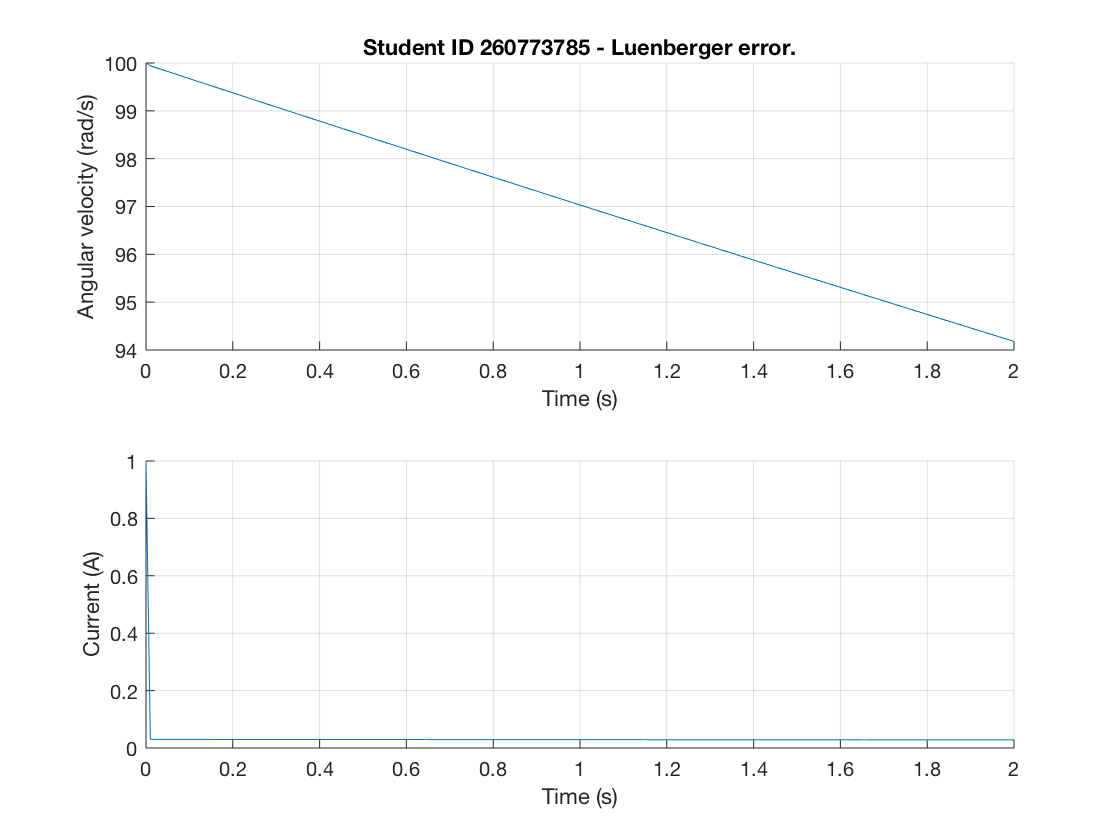


figure;
clf;
subplot(2, 1, 1)
hold on
plot(t, wErr);
xlabel('Time (s)')
ylabel('Angular velocity (rad/s)')
title(sprintf('Student ID %s - Luenberger error.', Students.ID));
grid on
subplot(2, 1, 2)
hold on
plot(t, iErr);
xlabel('Time (s)')
ylabel('Current (A)')
grid on

## *3. Open Loop Observer Design*

In this section we want to use the estimator designed above to estimate the states of the DC motor in an open loop structure. The representation of an open loop system with an estimator is given as follows:

<<fig_lab06_estimator.png>>

As you see, the estimator is like a parallel system that receives the input and output of the system and generates an estimate of the states.

We will generate a set of measurements for angular velocity from the DC Motor. For this we run the following experiment

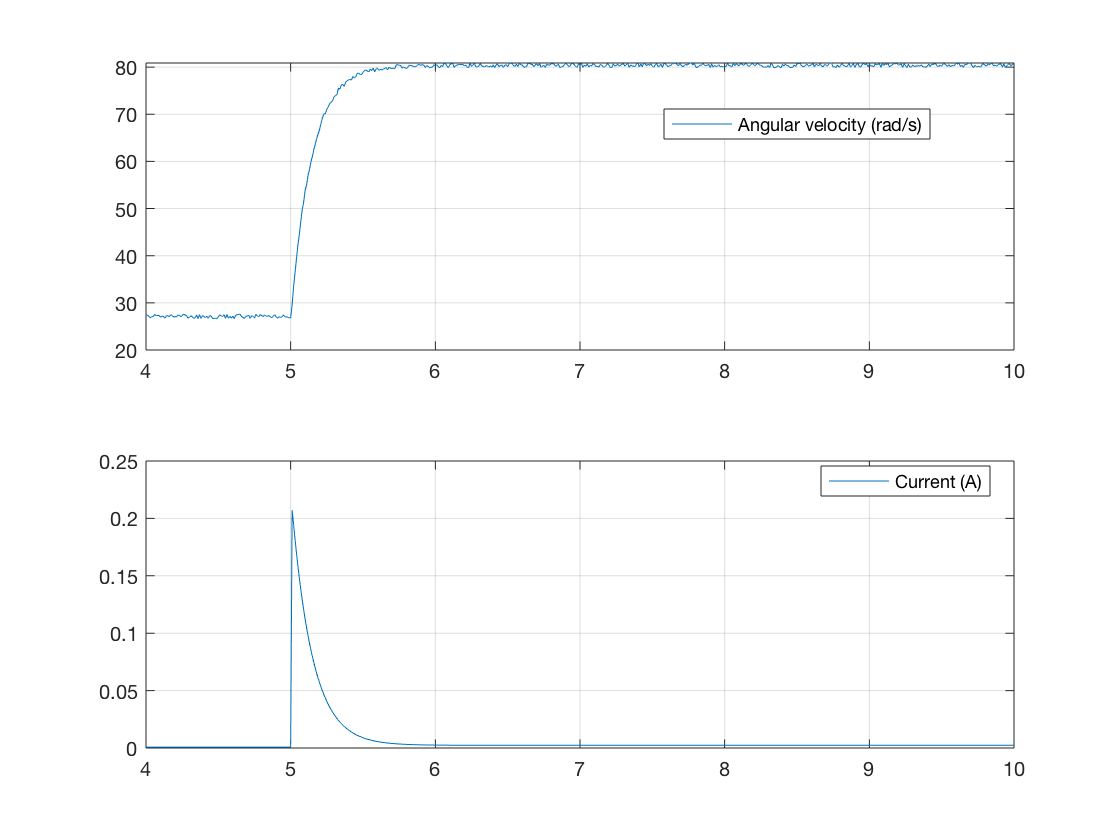

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
t = 0:dt:T; % Time array
TStart = 5; % Step start
wRef = zeros(size(t));
wRef(t < TStart) = 25;
wRef(t >= TStart) = 75;

N = 1 / (C * (-A)^(-1) * B);
Motor.reset();
Motor.input(N*wRef);
Motor.off();

Motor.save(Students,'Lab06.Data_Collection');

% Get results of driving Virtual DC Motor
v = Motor.voltage(t <= T);
i = Motor.current(t <= T);
w = Motor.velocity(t <= T);

% Plot results
figure;
clf;
subplot(2, 1, 1)
title(sprintf('Student ID %s - A step response experiment', Students.ID));
plot(t, w)
legend('Angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])
grid on
subplot(2, 1, 2)
plot(t, i)
legend('Current (A)', 'location', 'best');
xlim([TStart - 1, T])
grid on

Since we are manipulating the DC Motor in discrete time, we cannot use gains designed for the continuous system. We will need to convert these gains to their equivalent discrete gains.

First we define the system $G_o$ in a discrete form using the `c2d` function

Go_d = c2d(Go, dt, 'zoh')


Go_d =
 
  A = 
              x1         x2
   x1      0.942       3.45
   x2  -0.003834  -0.004108
 
  B = 
           u1
   x1   1.563
   x2  0.1132
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Now if $L$ is a Luenberger gain for ($A$, $C$) which places poles ($p_1$, $p_2$) . The equivalent $L_d$ gain will place the discrete poles ($\exp(p_1 T_s)$, $\exp(p_2 T_s)$) for the discrete system ($A_d$, $C_d$) . As an example, we can write

Ad = Go_d.A;
Bd = Go_d.B;
Cd = Go_d.C;
Ld = place(Ad', Cd', exp([p1, p2]*dt))'

Ld =    -0.1267
    0.1041


Finally, we should write the Luenberger equation in a discrete time:


$$ \hat{x}(n+1) = A_d \hat{x}(n) + B_d u(n) + L_d (y(n) - \hat{y}(n))$$


where ($A_d$, $B_d$) are discrete form of ($A$, $B$), and $L_d$ is the equivalent Luenberger gain of $L$ in discrete time.

## *Question 4 (2 marks)*

For the desired poles $P_{1,2} = -50 \pm 50 j$ of the Luenberger observer, complete the following code to design and test the state estimator.

p1 = 50 * (-1 + 1j);
p2 = 50 * (-1 - 1j);

% [Answer Here] Find the gain Ld

Ld = transpose(place(Ad', Cd', exp([p1, p2]*dt)));

% Simulate state estimation
xHat = zeros(2, length(t));
for n = 1:length(t) - 1
    v_ = N * wRef(n);
    % [Answer Here] Write the estimator dynamics here
    
    xHat(:, n+1) = Ad * xHat(:, n) + Bd * v_ + Ld * (w(n) - Cd * xHat(:,n));
    
end

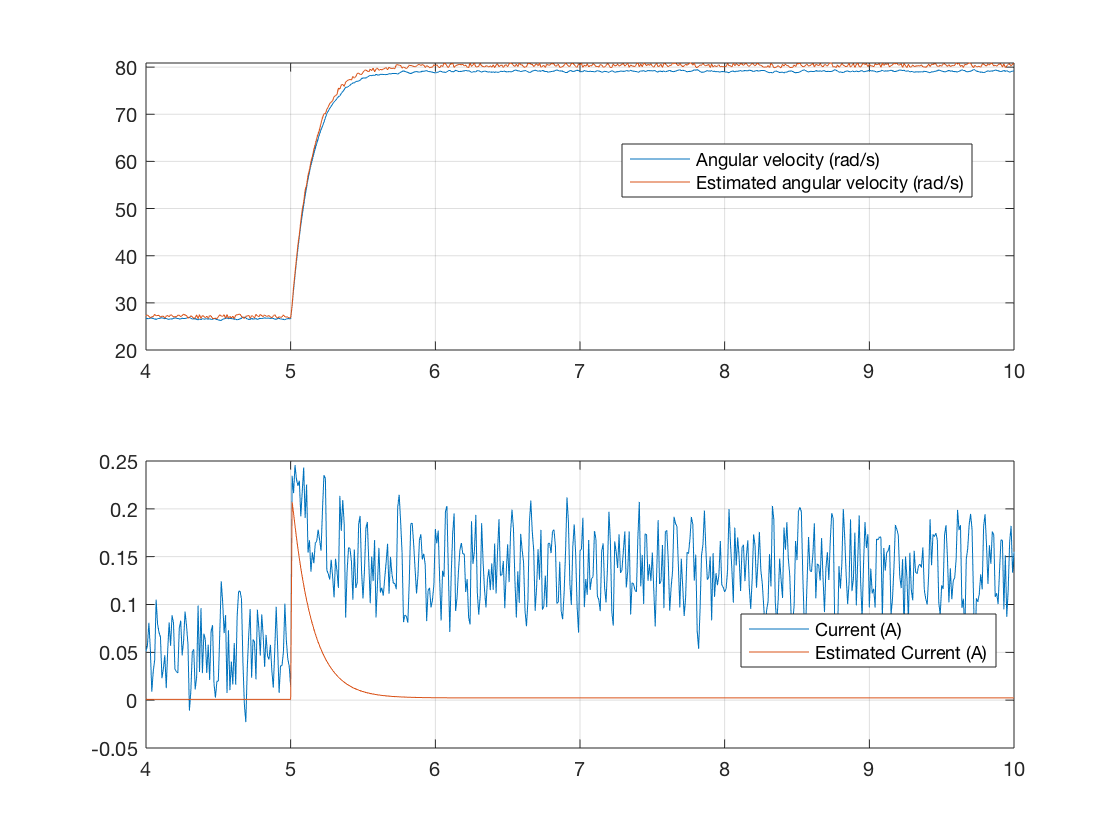

% Plot results
figure;
clf;

subplot(2, 1, 1)
title(sprintf('Student ID %s - State Estimator Test', Students.ID));
% [Answer here] Superpose the actual angular velocity and the estimated angular velocity
plot(t,xHat(1,:))
hold on 
plot(t,w)
legend('Angular velocity (rad/s)', ...
    'Estimated angular velocity (rad/s)', ...
    'location', 'best');
xlim([TStart - 1, T])
grid on
subplot(2, 1, 2)
% [Answer here] Plot current
plot(t,xHat(2,:))
hold on
plot(t,i)

legend('Current (A)', 'Estimated Current (A)', 'location', 'best');
xlim([TStart - 1, T])
grid on

## *Question 5 (1 marks)*

1. A discrete observer is called asymptotically stable if the observer error $e(n) = x(n) - \hat{x}(n)$ converges to zero when $n \to \infty$. For a discrete Luenberger observer, the observer error satisfies $e(n+1) = (A_d - L_d C_d) e(n)$ and therefore the Luenberger observer for this discrete-time system is asymptotically stable if and only if all of the eigenvalues of $(A_d - L_d C_d)$ are all inside the unit circle. Compute the eigenvalues of $(A_d - L_d C_d)$ in discrete time and determine whether the observer is asymptotically stable or not.

eigen3 = eig(Ad - Ld*Cd);
if(abs(eigen3(1)) < 1 && abs(eigen3(2)) < 1)
    disp('Yes they are asymptotically stable')
else
    disp('no')
end

Yes they are asymptotically stable


% they are astmptotically stable 

2. Based on the plot of the error in question 4, does the error go to zero? Does this confirm the asymptotically stability of the observer? If not justify your answer.

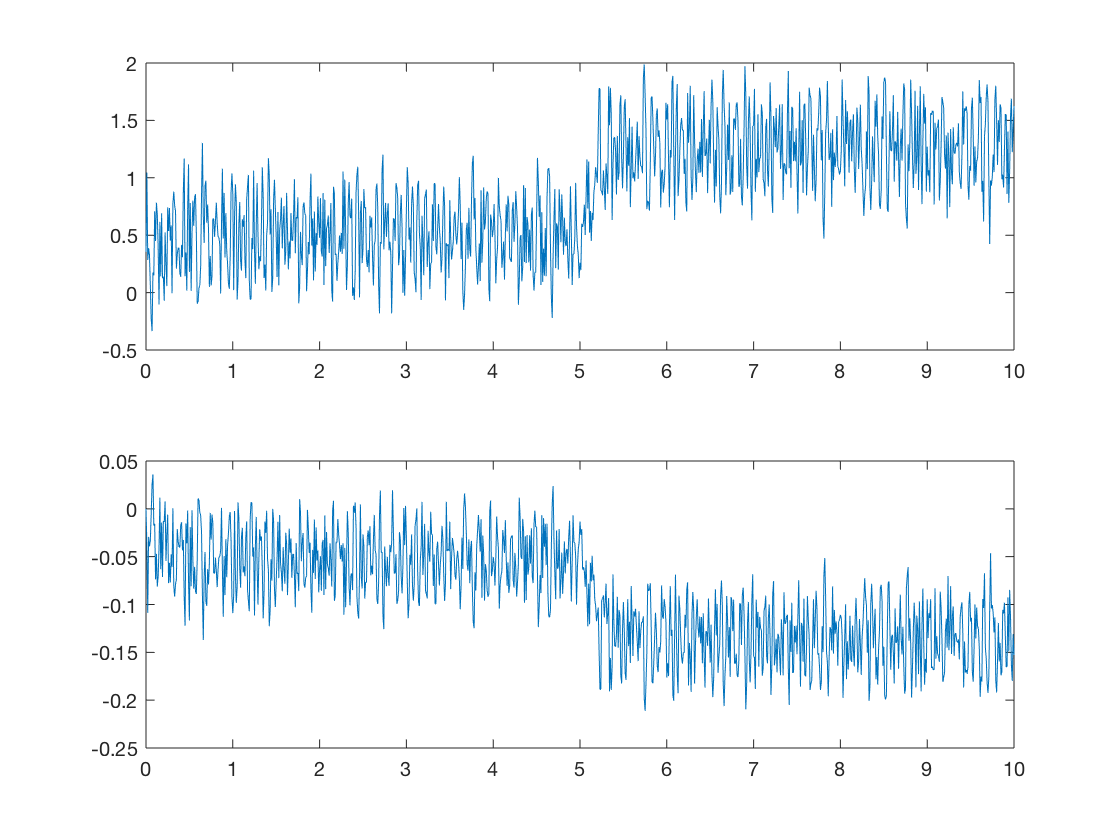

figure
subplot(2,1,1)
plot(t,w(:)' - xHat(1,:))

subplot(2,1,2)
plot(t,i(:)' - xHat(2,:))


% yes, the error in question 4 goes to zero

We can evaluate the goodness of the estimate by measuring the noise transmitted to the observer.

error_w = std(xHat(1, t > 6));
error_i = std(xHat(2, t > 6));
fprintf('Student ID %s - using gain [%.3f;%.3f]: error in angular velocity: %.3f - error in current: %.3f.\n', ...
    Students.ID, Ld, error_w, error_i);

Student ID 260773785 - using gain [-0.127;0.104]: error in angular velocity: 0.138 - error in current: 0.034.


## *Question 6 (3.0 marks)*

Repeat question 4 for the following other poles

- 
$$P_{1,2} = -250 \pm 250 j$$


- 
$$P_{1,2} = -500 \pm 500 j$$


Based on the standard deviation of the observed noise, which poles you choose for the observer?

p1 = 250 * (-1 + 1j);
p2 = 250 * (-1 - 1j);

% [Answer Here] Rerun the state estimator and calculate errors
pd2 = [p1 p2];
Ld2 = transpose(place(Ad',Cd',exp(pd2*dt)));

% Simulate state estimation
xHat = zeros(2, length(t));
for n = 1:length(t) - 1
    v_ = N * wRef(n);
    xHat(:, n+1) = Ad * xHat(:, n) + Bd * v_ + Ld2 * (w(n) - Cd * xHat(:,n));
end
error_w = std(xHat(1, t > 6));
error_i = std(xHat(2, t > 6));

fprintf('Student ID %s - using gain [%.3f;%.3f]: error in angular velocity: %.3f - error in current: %.3f.\n', ...
    Students.ID, Ld, error_w, error_i);

Student ID 260773785 - using gain [-0.127;0.104]: error in angular velocity: 0.310 - error in current: 0.001.


p1 = 500 * (-1 + 1j);
p2 = 500 * (-1 - 1j);

% [Answer Here] Rerun the state estimator and calculate errors
pd3 = [p1 p2];
Ld3 = transpose(place(Ad',Cd',exp(pd3*dt)));
% Simulate state estimation
xHat = zeros(2, length(t));
for n = 1:length(t) - 1
    v_ = N * wRef(n);
    xHat(:, n+1) = Ad * xHat(:, n) + Bd * v_ + Ld3 * (w(n) - Cd * xHat(:,n));
end
error_w = std(xHat(1, t > 6));
error_i = std(xHat(2, t > 6));

fprintf('Student ID %s - using gain [%.3f;%.3f]: error in angular velocity: %.3f - error in current: %.3f.\n', ...
    Students.ID, Ld, error_w, error_i);

Student ID 260773785 - using gain [-0.127;0.104]: error in angular velocity: 0.270 - error in current: 0.001.


% Answer here: which poles you choose for the observer?
%I choose poles -150 + j150 and -150 - j150 based on the error shown.

## **3. Closed-loop State Estimator for Velocity Control**

In this section, we want to use the estimated states with a state feedback controller to track a reference input, while satisfying the three specifications.

- Overshoot less than 20%.

- 5%-settling time less than 0.25 seconds.

- Steady state gain of 1 $\pm$ 5%.

The state feedback input to the system is


$$ v(t) = N \omega_{ref}(t) - K x(t) $$


Because the observation of the system is not complete and we don't have access to the full state of the system, we use the following control law instead:


$$ v(t) = N \omega_{ref}(t) - K \hat{x}(t) $$


where $K$ and $N$ are computed to satisfy the specifications.

ts = 0.25;
Mp = 0.2;
xi = -log(Mp) / sqrt(pi^2+log(Mp)^2);
wn = 3 / (ts * xi);

p1d = -wn * (xi + sqrt(1-xi^2) * 1i)

p1d = -12.0000 - 23.4238i

p2d = -wn * (xi - sqrt(1-xi^2) * 1i)

p2d = -12.0000 + 23.4238i


Kd = place(Ad, Bd, [exp(p1d*dt), exp(p2d*dt)]);
Nd = 1 / (Cd * (eye(2) - Ad + Bd * Kd)^(-1) * Bd);

## *Question 7 (1 marks)*

Complete the code to run a state feedback controller with a Luenberger estimator. You will need to design for the poles of the Luenberger estimator based on what you learned in the open-loop experiment.

% [Answer Here] Find the gain Ld (use place)

p1 = 250 * (-1 + 1j);
p2 = 250 * (-1 - 1j);
Ld = transpose(place(Ad',Cd',exp([p1 p2]*dt)));

xHat = zeros(2, length(t));
% Drive motor
Motor.reset();
for n = 1:length(t)
    t_ = t(n);
    Motor.wait(t_);
    
    w_ = Motor.velocity_final; % the final reading of velocity by sensor
    if t_ < TStart
        v_ = N * wRef(n);
    else
        v_ = Nd * wRef(n) - Kd * xHat(:, n);
    end
    if n < length(t)
        % [Answer Here] write the dynamics of the estimator here
        
        xHat(:, n+1) = Ad * xHat(:, n) + Bd * v_ + Ld * (w(n) - Cd * xHat(:,n));
        
    end
    Motor.input(v_);
end
Motor.off();
Motor.save(Students, 'Lab06.Q7');

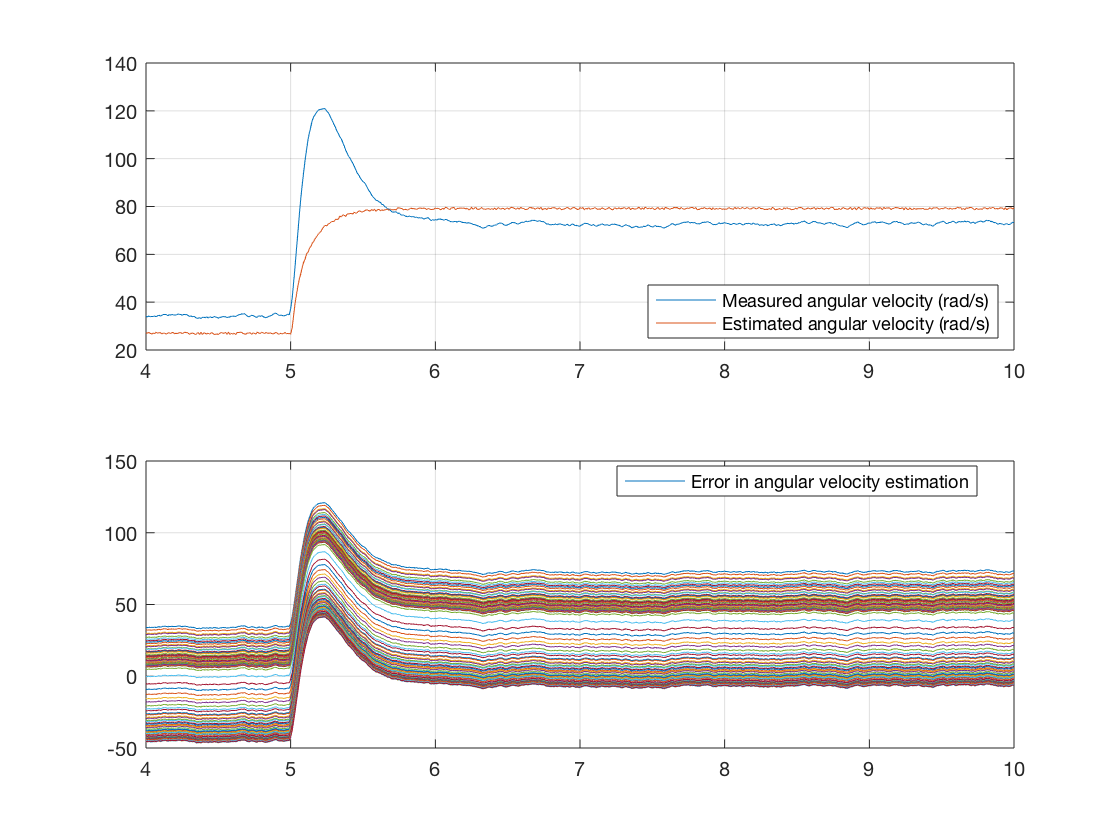

% Get results of driving Virtual DC Motor
v = Motor.voltage(t <= T);
i = Motor.current(t <= T);
w = Motor.velocity(t <= T);

% Plot results
figure;
clf;

subplot(2, 1, 1)
title(sprintf('Student ID %s - speed true and estimated state', Students.ID));
% [Answer Here] Superpose measured and estimated angular velocity
plot(t,w)
hold on
plot(t,xHat(1,:))

legend('Measured angular velocity (rad/s)', ...
    'Estimated angular velocity (rad/s)', ...
    'location', 'southeast');

xlim([TStart - 1, T])
grid on

subplot(2, 1, 2)

% [Answer Here] Plot the error between measured and estimated angular
% velocity
plot(t,w' - xHat(1,:))

legend('Error in angular velocity estimation', 'location', 'best');
xlim([TStart - 1, T])
grid on

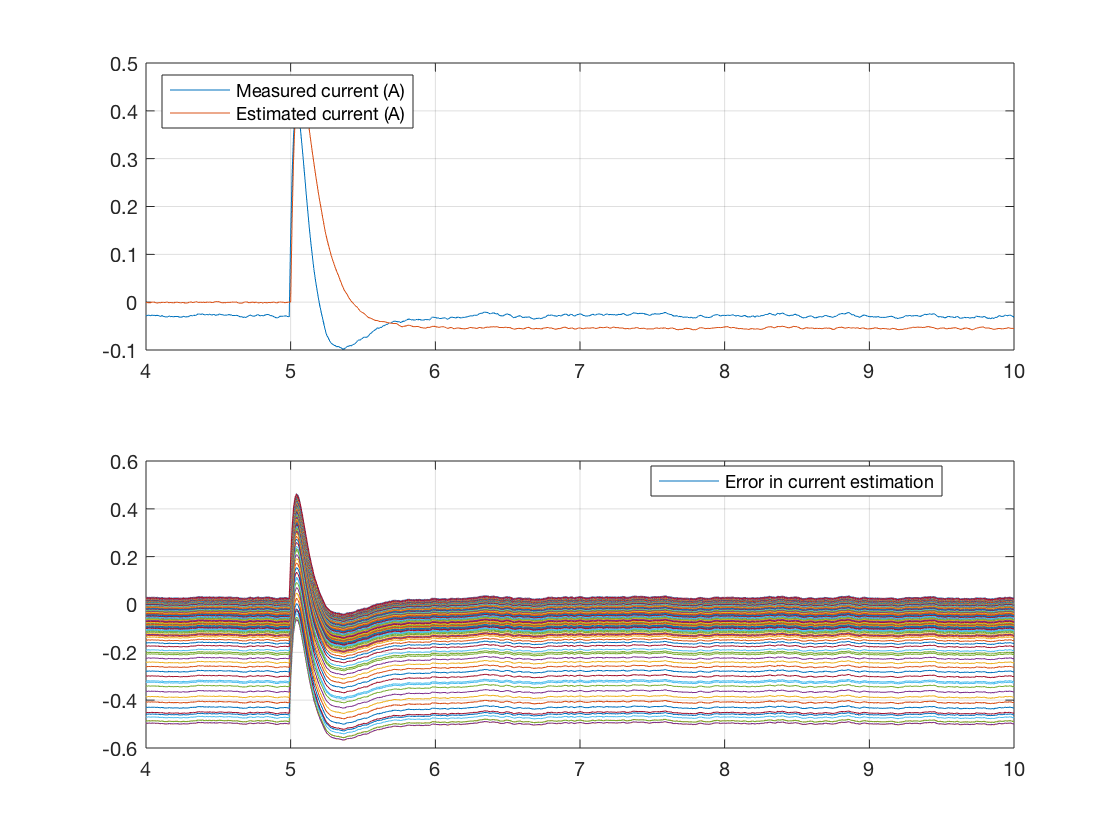

figure;
clf;

subplot(2, 1, 1)
title(sprintf('Student ID %s - Current true and estimated state', Students.ID));
% [Answer Here] Superpose measured and estimated current
plot(t,i)
hold on
plot(t,xHat(2,:))

legend('Measured current (A)', ...
    'Estimated current (A)', ...
    'location', 'northwest');

xlim([TStart - 1, T])
grid on

subplot(2, 1, 2)
% [Answer Here] Plot the error for current here
plot(t,i' - xHat(2,:))

legend('Error in current estimation', 'location', 'best');
xlim([TStart - 1, T])
grid on